%% Workshop Main File - Part 2
% This script demonstrates the data preprocessing, analysis, and visualization techniques 
% using 'lamdumpread2', a custom function for reading LAMMPS dump files.

% File Structure (change your local path to reflect the content)
% ├── example2.m
% └── ...
% └── data folder (dumps/pub1/)

%INRAE\Olivier Vitrac, Han Chen (rev. 2023-08-30,2023-08-31)

%% Initialization and Preprocessing 
% -------------------------------------------------
% Turn preprocessing on or off based on `PREPROCESS_FLAG`. 
% 'lamdumpread2' splits large 3D dump files if the flag is true.

statvec = @(f,before,after) dispf('%s: %s%d values | average = %0.5g %s', before, ...
    cell2mat(cellfun(@(x) sprintf(' %0.1f%%> %10.4g | ', x, prctile(f, x)), {2.5, 25, 50, 75, 97.5}, 'UniformOutput', false)), ...
    length(f), mean(f),after); % user function to display statistics on vectors (usage:  statvec(f,'myvar','ok'))

PREPROCESS_FLAG = false;
if PREPROCESS_FLAG
    datafolder = './dumps/pub1/';
    lamdumpread2(fullfile(datafolder,'dump.*'),'split'); % for large 3D
end

%% File-specific Processing (same file as in Example1.m but larger)
% -----------------------------------------------------------------
% A specific dump file is selected and pre-processed to extract data and 
% save to default folders for further operations.
datafolder = './dumps/pub1/';
dumpfile = 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle';
datafolder = lamdumpread2(fullfile(datafolder,dumpfile),'search'); % fix datafolder based on initial guess

Look for 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle'... (be patient)
...found in './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary'

The dumpfile 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle' has been found with the method 'splitfolder'
	in the folder: ./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary
the original search started in ./dumps/pub1
The frame (split) folder is: ./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
The first frame (split) is located in: ./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle/TIMESTEP_000000000.mat
The prefetch is split in several files.
1014 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	

defaultfiles = lamdumpread2(fullfile(datafolder,dumpfile),'default'); % default folder (just for check)

%% Data Extraction
% -------------------------------------------------
% Extract the types of atoms and the list of available frames
X0 = lamdumpread2(fullfile(datafolder,dumpfile)); % default frame

The prefetch is split in several files.
1014 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	  Column 06	  Column 07	  Column 08	  Column 09	  Column 10	
        0	   102000	   204000	   306000	   408000	   510000	   612000	   714000	   816000	   918000	
     1000	   103000	   205000	   307000	   409000	   511000	   613000	   715000	   817000	   919000	
     2000	   104000	   206000	   308000	   410000	   512000	   614000	   716000	   818000	   920000	
     3000	   105000	   207000	   309000	   411000	   513000	   615000	   717000	   819000	   921000	
     4000	   106000	   208000	   310000	   412000	   514000	   616000	   718000	   820000	   922000	
     5000	   107000	   209000	   311000	   413000	   515000	   617000	   719000	   821000	   923000	
     6000	   108000	   210000	   312000	   414000	   516000	   618000	   720000	   822000	   924000	
     7000	   109000	   211000	   313000	   415000	   517000	   619000	   721000	   823000	   925000	
  

natoms = X0.NUMBER;
timesteps = X0.TIMESTEPS;
atomtypes = unique(X0.ATOMS.type);
ntimesteps = length(timesteps);

% Extract the middle frame (i.e. in the middle of the simulation duration)
% X0 is too far from steady state for advanced analysis
Xmiddle = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps(ceil(ntimesteps/2))); % middle frame

Use the prefetch (split: TIMESTEP 506000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000506000.mat		27-Jul-2023 21:17:15		8.5 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.317 s



% Extract the number of beads for each type
% guess the bead type for the fluid (the most populated)
% same guess for the particle (the less populated)
T = X0.ATOMS.type;
natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
[~,fluidtype] = max(natomspertype);
[~,solidtype] = min(natomspertype);
walltypes = setdiff(atomtypes,[fluidtype,solidtype]);

% Estimate the fluid bead size
% This step uses for more accuracy the buildVerletList()
fluidxyz = X0.ATOMS{T==fluidtype,{'x','y','z'}};
fluidid = X0.ATOMS{T==fluidtype,'id'};
nfluidatoms = length(fluidid);
nsolidatoms = natomspertype(solidtype);
% first estimate assuming that the bead is a cube
boxdims = X0.BOX(:,2) - X0.BOX(:,1);
Vbead_guess = prod(boxdims)/natoms;
rbead_guess = (3/(4*pi)*Vbead_guess)^(1/3);
cutoff = 3*rbead_guess;
[verletList,cutoff,dmin,config,dist] = buildVerletList(fluidxyz,cutoff);

Build Verlet list by searching in blocks...
... done in 0.3387 s with 729 search blocks | minimum distance 2.083e-05
	 Sort the Verlet list...
	 ... done in 0.552 s
buildVerletList: all done in 25.8 s for 215025 atoms


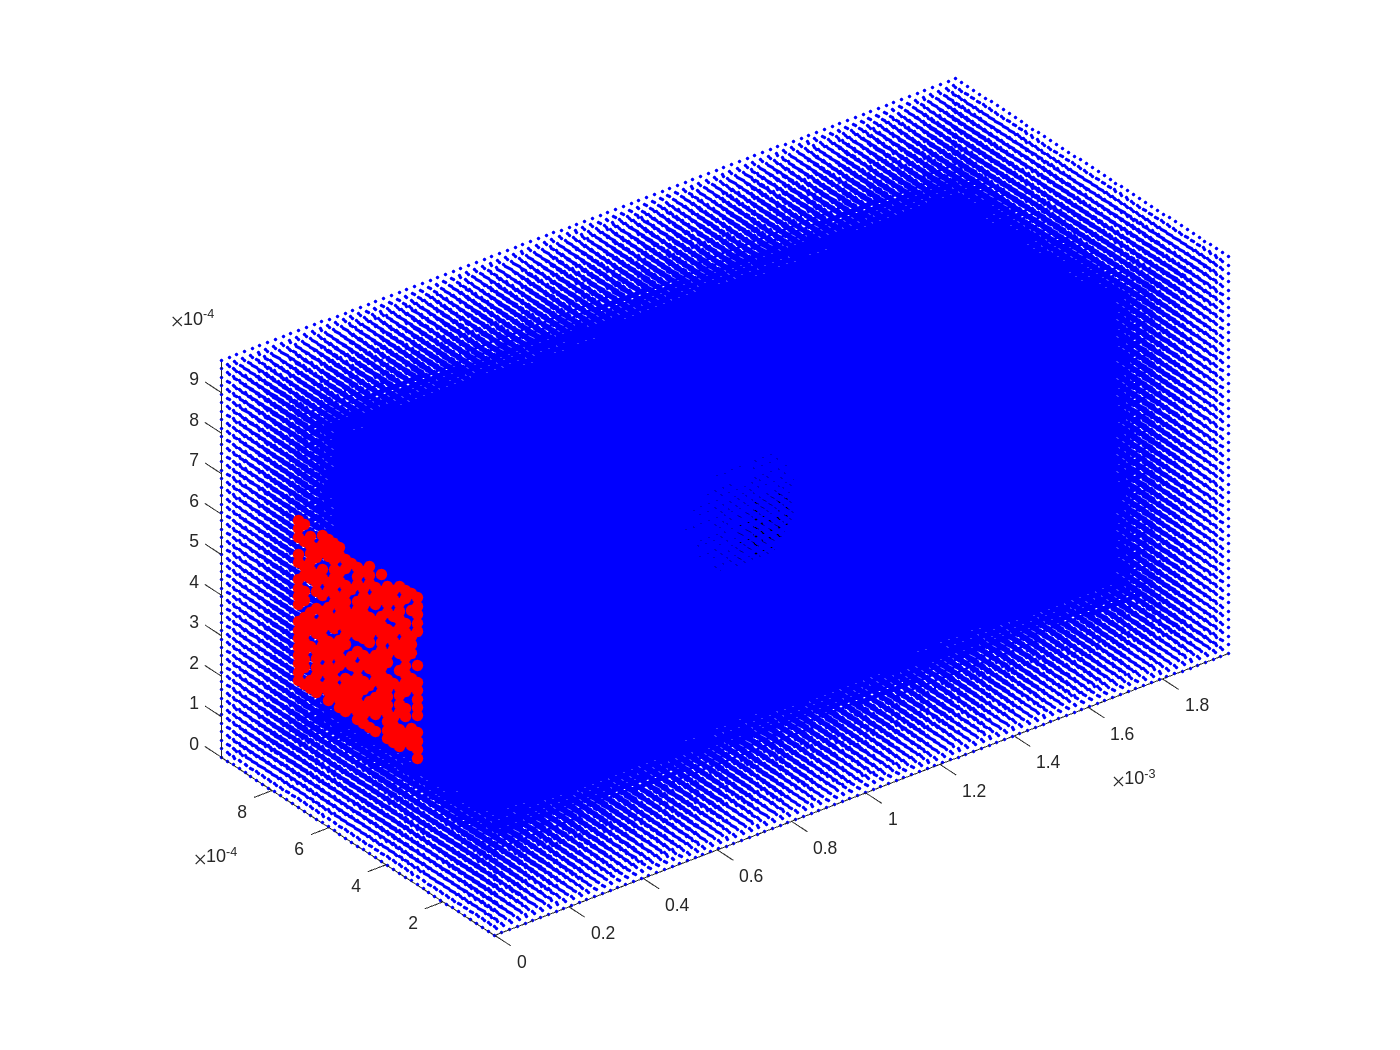

rbead = dmin/2;

% find the direction of the flow (largest dimension)
[~,iflow] = max(boxdims);
iothers = setdiff(1:size(X0.BOX,1),iflow);

% separate top and bottom walls
vel = {'vx','vy','vz'};
wall1vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(1),vel{iflow}}; wall1vel = wall1vel(1);
wall2vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(2),vel{iflow}}; wall2vel = wall2vel(1);
[wallvel,iwall] = sort([wall1vel,wall2vel],'descend'); % 1 is top (>0), 2 is bottom;
walltypes = walltypes(iwall);

% find the position of the particle (i.e., obstacle) placed in the flow (from the middle frame)
solidxyz = Xmiddle.ATOMS{T==solidtype,{'x','y','z'}};
solidid = Xmiddle.ATOMS{T==solidtype,'id'};
solidbox = [min(solidxyz);max(solidxyz)]';

%% Data Preprocessing for Selected Particles
% -------------------------------------------------
% This part is a repetition of the content of example1. It generate the streamlines for particles 
% at the left. It requires 5 min and it can be skipped as it not used for stresses.
% note: the duration of the simulation enables the particles in the center (slowest part) to
% cross only half of the cell.

% Pick n particles randomly from the left inlet and included in the mask of the solid (initial frame)
n = 300;
tol = 0.5; % add 40% particles around
selectionbox = NaN(3,2);
selectionbox(iflow,:) = [X0.BOX(iflow,1), X0.BOX(iflow,1)+2*rbead];
selectionbox(iothers,:) =  (1+tol)*(solidbox(iothers,2)-solidbox(iothers,1))*[-1 1]/2 ...
    + (solidbox(iothers,1)+solidbox(iothers,2)) * [1 1]/2;
ok = true(nfluidatoms,1);
for c = 1:3
    ok = ok & (fluidxyz(:,c)>=selectionbox(c,1)) & (fluidxyz(:,c)<=selectionbox(c,2));
end
icandidates = find(ok);
iselected = icandidates(MDunidrnd(length(icandidates),n));
selectedid = fluidid(iselected); % ID to be used
% plot selected particles and other ones
figure, hold on
plot3D(fluidxyz,'b.')
plot3D(fluidxyz(iselected,:),'ro','markerfacecolor','r')
plot3D(solidxyz,'ks','markerfacecolor','k')
view(3), axis equal


% Generate the trajectory for the selected particles (for all frames)
% All data are loaded with Lamdumpread2() with a single call using 'usesplit'
% each split is loaded individually and only atoms matching selectedid are stored
% all atoms are sorted as selectedid (no need to sort them)
Xselection = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,selectedid);

Use the prefetch (split: TIMESTEP 0) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		27-Jul-2023 20:52:07		1.1 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 1000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000001000.mat		27-Jul-2023 20:52:09		6.3 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 2000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.uls


% Collect the trajectory of the solid particle for all frames
Xsolid = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,solidid);

Use the prefetch (split: TIMESTEP 0) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		27-Jul-2023 20:52:07		1.1 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 1000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000001000.mat		27-Jul-2023 20:52:09		6.3 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 2000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.uls

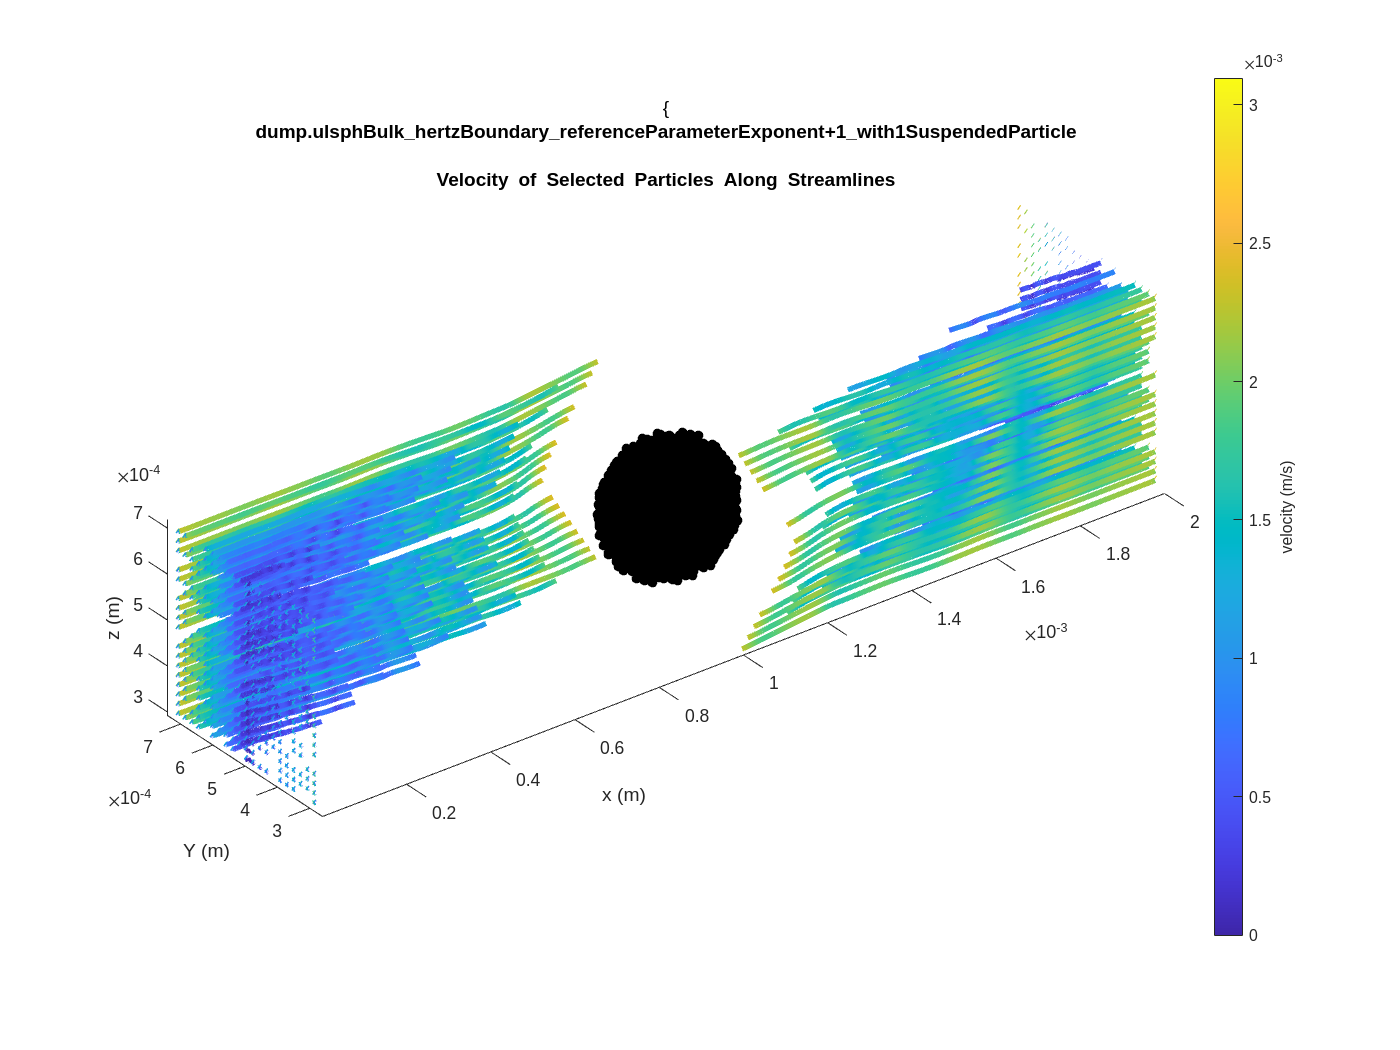


% Store the trajectories stored in a ntimesteps x 3 x n matrix
% missing data will
[seltraj,selveloc] = deal(NaN(ntimesteps,3,n,'single'));
solidtraj = NaN(ntimesteps,3,nsolidatoms,'double');
goodframes = true(ntimesteps,1);
for it = 1:ntimesteps
    % read fluid atoms
    selframe = Xselection.ATOMS(Xselection.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(selframe,1);
    if nfoundatoms<n % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d fluid atoms missing',it,ntimesteps,timesteps(it),n-nfoundatoms,n)
        [~,iatoms,jatoms] = intersect(selectedid,selframe.id,'stable');
        seltraj(it,:,iatoms) = permute(selframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        seltraj(it,:,:) = permute(selframe{:,{'x','y','z'}},[3 2 1]);
        selveloc(it,:,:) = permute(selframe{:,{'vx','vy','vz'}},[3 2 1]);
    end
    % read solid atoms
    solidframe = Xsolid.ATOMS(Xsolid.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(solidframe,1);
    if nfoundatoms<nsolidatoms % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d solid atoms missing',it,ntimesteps,timesteps(it),nsolidatoms-nfoundatoms,nsolidatoms)
        [~,iatoms,jatoms] = intersect(solidid,solidframe.id,'stable');
        solidtraj(it,:,iatoms) = permute(solidframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        solidtraj(it,:,:) = permute(solidframe{:,{'x','y','z'}},[3 2 1]);
    end
end
% velocity magnitude for the fluid particles
selveloc_magnitude = squeeze(sqrt(sum(selveloc.^2, 2)));

% Trajectory Visualization
% -------------------------------------------------
% streamlines with color representing velocity magnitude
figure, hold on
col = parula(n);
for i=1:n
    jumps = [1;ntimesteps+1];
    for d=1:3
        jumps = unique([jumps;find(abs(diff(seltraj(:,d,i)))>boxdims(d)/2)+1]);
    end
    for j=1:length(jumps)-1
        u = jumps(j):jumps(j+1)-1;
        streamline = seltraj(u, :, i);
        color_line3(streamline(:, 1), streamline(:, 2), streamline(:, 3), selveloc_magnitude(u, i), 'linewidth', 3);
        % faster method but without streamline
        %plot3(traj(u,1,i),traj(u,2,i),traj(u,3,i),'-','linewidth',3,'color',col(i,:))
    end
end
plot3D(solidxyz,'ko','markerfacecolor','k','markersize',5)
view(3), axis equal
title({'\rm{' strrep(dumpfile, '_', '\_') '}:' '\bf{Velocity of Selected Particles Along Streamlines}'}, 'Interpreter', 'tex')
xlabel('x (m)'), ylabel('Y (m)'), zlabel('z (m)')
hc = colorbar; hc.Label.String = 'velocity (m/s)';

Use the prefetch (split: TIMESTEP 101000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000101000.mat		27-Jul-2023 20:58:47		7.7 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.307 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[1/9] TIMESTEP = 101000 (plot)


Build Verlet list by searching in blocks...
... done in 0.1497 s with 1584 search blocks | minimum distance 1.54e-05
	 Sort the Verlet list...
	 ... done in 0.69 s
buildVerletList: all done in 29.5 s for 313344 atoms


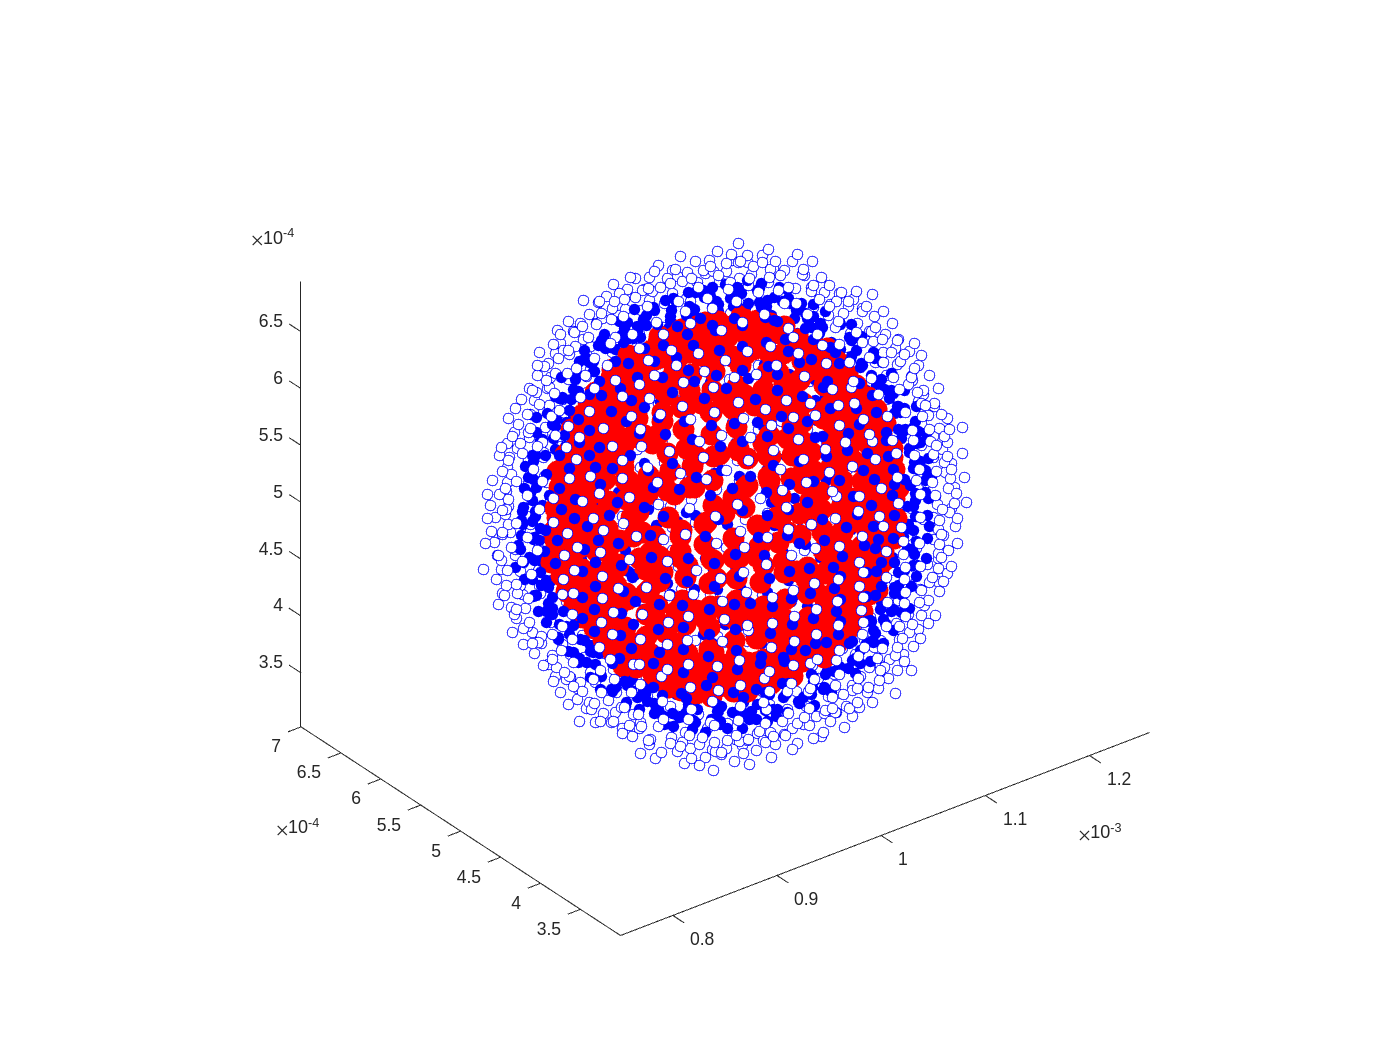

	number of fluid atoms in contact with solid 853


	number of solid atoms in contact with fluid 566 (neighbors 1094)


Calculate the 1947 x 1947 pair distances...
	 ... done in 0.00512 s
Find atoms within cuttoff...
	 ... done in 0.00596 s
Build the Verlet list...
	 ... done in 0.0492 s [min=11, median=20, max=27]
	 Sort the Verlet list...
	 ... done in 0.00535 s
buildVerletList: all done in 0.0774 s for 1947 atoms


Calculate Landshoff forces between [1947 x 3] atoms...
	 ... done in 0.0262 s


Landshoff:  2.5%>  5.191e+11 |  25.0%>  1.297e+12 |  50.0%>  1.875e+12 |  75.0%>  2.735e+12 |  97.5%>  4.909e+12 | 853 values | average = 2.1112e+12 <-- TIMESTEP: 101000


Calculate the 1 x 1419 pair distances...
	 ... done in 0.000775 s
Find atoms within cuttoff...
	 ... done in 0.00117 s
Build the Verlet list...
	 ... done in 0.01 s [min=0, median=0, max=10]
	 Sort the Verlet list...
	 ... done in 0.0031 s
buildVerletList: all done in 0.0184 s for 1419 atoms


Hertz:  2.5%>   1.23e-08 |  25.0%>   3.92e-08 |  50.0%>  5.791e-08 |  75.0%>  8.767e-08 |  97.5%>  1.032e-07 | 566 values | average = 6.1184e-08 <-- TIMESTEP: 101000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.377e-05


Use the prefetch (split: TIMESTEP 202000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000202000.mat		27-Jul-2023 21:03:44		8.1 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.316 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[2/9] TIMESTEP = 202000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.02827 s with 1584 search blocks | minimum distance 1.506e-05
	 Sort the Verlet list...
	 ... done in 0.72 s
buildVerletList: all done in 30.5 s for 313344 atoms


Calculate the 1941 x 1941 pair distances...
	 ... done in 0.00436 s
Find atoms within cuttoff...
	 ... done in 0.00573 s
Build the Verlet list...
	 ... done in 0.0499 s [min=10, median=21, max=28]
	 Sort the Verlet list...
	 ... done in 0.00542 s
buildVerletList: all done in 0.0771 s for 1941 atoms


Calculate Landshoff forces between [1941 x 3] atoms...
	 ... done in 0.0242 s


Landshoff:  2.5%>  5.265e+11 |  25.0%>  1.214e+12 |  50.0%>  1.736e+12 |  75.0%>   2.39e+12 |  97.5%>  4.223e+12 | 874 values | average = 1.8927e+12 <-- TIMESTEP: 202000


Calculate the 1 x 1453 pair distances...
	 ... done in 0.000715 s
Find atoms within cuttoff...
	 ... done in 0.000883 s
Build the Verlet list...
	 ... done in 0.00966 s [min=0, median=0, max=10]
	 Sort the Verlet list...
	 ... done in 0.00285 s
buildVerletList: all done in 0.0162 s for 1453 atoms


Hertz:  2.5%>  1.692e-08 |  25.0%>   3.97e-08 |  50.0%>   6.58e-08 |  75.0%>  8.903e-08 |  97.5%>  1.043e-07 | 579 values | average = 6.2941e-08 <-- TIMESTEP: 202000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.376e-05


Use the prefetch (split: TIMESTEP 304000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000304000.mat		27-Jul-2023 21:08:00		8.3 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.32 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[3/9] TIMESTEP = 304000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.07161 s with 1584 search blocks | minimum distance 1.441e-05
	 Sort the Verlet list...
	 ... done in 0.698 s
buildVerletList: all done in 29.4 s for 313344 atoms


Calculate the 1944 x 1944 pair distances...
	 ... done in 0.00428 s
Find atoms within cuttoff...
	 ... done in 0.00549 s
Build the Verlet list...
	 ... done in 0.0492 s [min=11, median=21, max=28]
	 Sort the Verlet list...
	 ... done in 0.00544 s
buildVerletList: all done in 0.0767 s for 1944 atoms


Calculate Landshoff forces between [1944 x 3] atoms...
	 ... done in 0.0241 s


Landshoff:  2.5%>  4.509e+11 |  25.0%>  1.089e+12 |  50.0%>  1.585e+12 |  75.0%>  2.191e+12 |  97.5%>  3.868e+12 | 903 values | average = 1.7304e+12 <-- TIMESTEP: 304000


Calculate the 1 x 1492 pair distances...
	 ... done in 0.000783 s
Find atoms within cuttoff...
	 ... done in 0.000909 s
Build the Verlet list...
	 ... done in 0.00961 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.00276 s
buildVerletList: all done in 0.016 s for 1492 atoms


Hertz:  2.5%>  7.827e-09 |  25.0%>  3.956e-08 |  50.0%>  6.567e-08 |  75.0%>  9.011e-08 |  97.5%>  1.067e-07 | 589 values | average = 6.3308e-08 <-- TIMESTEP: 304000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.374e-05


Use the prefetch (split: TIMESTEP 405000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000405000.mat		27-Jul-2023 21:12:42		8.4 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.305 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[4/9] TIMESTEP = 405000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.4996 s with 1584 search blocks | minimum distance 1.37e-05
	 Sort the Verlet list...
	 ... done in 0.721 s
buildVerletList: all done in 29.9 s for 313344 atoms


Calculate the 1938 x 1938 pair distances...
	 ... done in 0.00494 s
Find atoms within cuttoff...
	 ... done in 0.00543 s
Build the Verlet list...
	 ... done in 0.05 s [min=11, median=21, max=28]
	 Sort the Verlet list...
	 ... done in 0.00539 s
buildVerletList: all done in 0.0775 s for 1938 atoms


Calculate Landshoff forces between [1938 x 3] atoms...
	 ... done in 0.0237 s


Landshoff:  2.5%>  5.616e+11 |  25.0%>  1.123e+12 |  50.0%>  1.647e+12 |  75.0%>  2.433e+12 |  97.5%>  4.392e+12 | 906 values | average = 1.8581e+12 <-- TIMESTEP: 405000


Calculate the 1 x 1495 pair distances...
	 ... done in 0.000818 s
Find atoms within cuttoff...
	 ... done in 0.000958 s
Build the Verlet list...
	 ... done in 0.00969 s [min=0, median=0, max=10]
	 Sort the Verlet list...
	 ... done in 0.00278 s
buildVerletList: all done in 0.0162 s for 1495 atoms


Hertz:  2.5%>  1.085e-08 |  25.0%>  3.983e-08 |  50.0%>  6.641e-08 |  75.0%>  9.083e-08 |  97.5%>  1.084e-07 | 588 values | average = 6.4346e-08 <-- TIMESTEP: 405000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.374e-05


Use the prefetch (split: TIMESTEP 506000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000506000.mat		27-Jul-2023 21:17:15		8.5 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.291 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[5/9] TIMESTEP = 506000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.4025 s with 1584 search blocks | minimum distance 1.479e-05
	 Sort the Verlet list...
	 ... done in 0.715 s
buildVerletList: all done in 29.3 s for 313344 atoms


Calculate the 1947 x 1947 pair distances...
	 ... done in 0.00379 s
Find atoms within cuttoff...
	 ... done in 0.00555 s
Build the Verlet list...
	 ... done in 0.0538 s [min=11, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.00556 s
buildVerletList: all done in 0.0812 s for 1947 atoms


Calculate Landshoff forces between [1947 x 3] atoms...
	 ... done in 0.0243 s


Landshoff:  2.5%>  4.298e+11 |  25.0%>  1.084e+12 |  50.0%>  1.555e+12 |  75.0%>   2.22e+12 |  97.5%>   4.04e+12 | 911 values | average = 1.7515e+12 <-- TIMESTEP: 506000


Calculate the 1 x 1483 pair distances...
	 ... done in 0.000747 s
Find atoms within cuttoff...
	 ... done in 0.000875 s
Build the Verlet list...
	 ... done in 0.00985 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.00269 s
buildVerletList: all done in 0.0162 s for 1483 atoms


Hertz:  2.5%>  1.877e-08 |  25.0%>  4.064e-08 |  50.0%>  6.849e-08 |  75.0%>  9.246e-08 |  97.5%>  1.089e-07 | 572 values | average = 6.6237e-08 <-- TIMESTEP: 506000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.376e-05


Use the prefetch (split: TIMESTEP 608000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000608000.mat		27-Jul-2023 21:21:52		8.6 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.295 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[6/9] TIMESTEP = 608000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.4285 s with 1584 search blocks | minimum distance 1.476e-05
	 Sort the Verlet list...
	 ... done in 0.721 s
buildVerletList: all done in 29.3 s for 313344 atoms


Calculate the 1930 x 1930 pair distances...
	 ... done in 0.0041 s
Find atoms within cuttoff...
	 ... done in 0.00551 s
Build the Verlet list...
	 ... done in 0.049 s [min=10, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.00537 s
buildVerletList: all done in 0.0763 s for 1930 atoms


Calculate Landshoff forces between [1930 x 3] atoms...
	 ... done in 0.0236 s


Landshoff:  2.5%>  4.498e+11 |  25.0%>  1.021e+12 |  50.0%>  1.524e+12 |  75.0%>  2.137e+12 |  97.5%>  3.778e+12 | 906 values | average = 1.6629e+12 <-- TIMESTEP: 608000


Calculate the 1 x 1478 pair distances...
	 ... done in 0.000803 s
Find atoms within cuttoff...
	 ... done in 0.000905 s
Build the Verlet list...
	 ... done in 0.00962 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.0028 s
buildVerletList: all done in 0.0161 s for 1478 atoms


Hertz:  2.5%>  1.273e-08 |  25.0%>   4.06e-08 |  50.0%>  6.873e-08 |  75.0%>  9.134e-08 |  97.5%>  1.078e-07 | 572 values | average = 6.5571e-08 <-- TIMESTEP: 608000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.375e-05


Use the prefetch (split: TIMESTEP 709000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000709000.mat		27-Jul-2023 21:26:29		8.6 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.296 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[7/9] TIMESTEP = 709000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.4343 s with 1584 search blocks | minimum distance 1.364e-05
	 Sort the Verlet list...
	 ... done in 0.717 s
buildVerletList: all done in 29.2 s for 313344 atoms


Calculate the 1940 x 1940 pair distances...
	 ... done in 0.0049 s
Find atoms within cuttoff...
	 ... done in 0.00556 s
Build the Verlet list...
	 ... done in 0.0493 s [min=10, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.00542 s
buildVerletList: all done in 0.0782 s for 1940 atoms


Calculate Landshoff forces between [1940 x 3] atoms...
	 ... done in 0.0237 s


Landshoff:  2.5%>  6.285e+11 |  25.0%>  1.284e+12 |  50.0%>  1.815e+12 |  75.0%>    2.5e+12 |  97.5%>   3.92e+12 | 899 values | average = 1.9554e+12 <-- TIMESTEP: 709000


Calculate the 1 x 1464 pair distances...
	 ... done in 0.000763 s
Find atoms within cuttoff...
	 ... done in 0.000898 s
Build the Verlet list...
	 ... done in 0.00961 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.00282 s
buildVerletList: all done in 0.016 s for 1464 atoms


Hertz:  2.5%>  1.699e-08 |  25.0%>  4.042e-08 |  50.0%>  6.717e-08 |  75.0%>  9.122e-08 |  97.5%>  1.076e-07 | 564 values | average = 6.5112e-08 <-- TIMESTEP: 709000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.378e-05


Use the prefetch (split: TIMESTEP 811000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000811000.mat		27-Jul-2023 21:31:05		8.7 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.296 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[8/9] TIMESTEP = 811000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.3115 s with 1584 search blocks | minimum distance 1.456e-05
	 Sort the Verlet list...
	 ... done in 0.723 s
buildVerletList: all done in 29.2 s for 313344 atoms


Calculate the 1925 x 1925 pair distances...
	 ... done in 0.00433 s
Find atoms within cuttoff...
	 ... done in 0.0055 s
Build the Verlet list...
	 ... done in 0.0487 s [min=10, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.0053 s
buildVerletList: all done in 0.0757 s for 1925 atoms


Calculate Landshoff forces between [1925 x 3] atoms...
	 ... done in 0.0239 s


Landshoff:  2.5%>  4.628e+11 |  25.0%>  1.179e+12 |  50.0%>  1.684e+12 |  75.0%>  2.352e+12 |  97.5%>  3.913e+12 | 883 values | average = 1.8366e+12 <-- TIMESTEP: 811000


Calculate the 1 x 1456 pair distances...
	 ... done in 0.000722 s
Find atoms within cuttoff...
	 ... done in 0.000866 s
Build the Verlet list...
	 ... done in 0.00954 s [min=0, median=0, max=10]
	 Sort the Verlet list...
	 ... done in 0.00267 s
buildVerletList: all done in 0.0157 s for 1456 atoms


Hertz:  2.5%>  1.756e-08 |  25.0%>  4.058e-08 |  50.0%>  6.734e-08 |  75.0%>  8.966e-08 |  97.5%>  1.062e-07 | 573 values | average = 6.4345e-08 <-- TIMESTEP: 811000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.378e-05


Use the prefetch (split: TIMESTEP 912000) folder (instead of './dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000912000.mat		27-Jul-2023 21:35:16		8.8 MBytes		./dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.298 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[9/9] TIMESTEP = 912000 (plot)


Build Verlet list by searching in blocks...
... done in 0.4458 s with 1584 search blocks | minimum distance 1.461e-05
	 Sort the Verlet list...
	 ... done in 0.722 s
buildVerletList: all done in 29.2 s for 313344 atoms


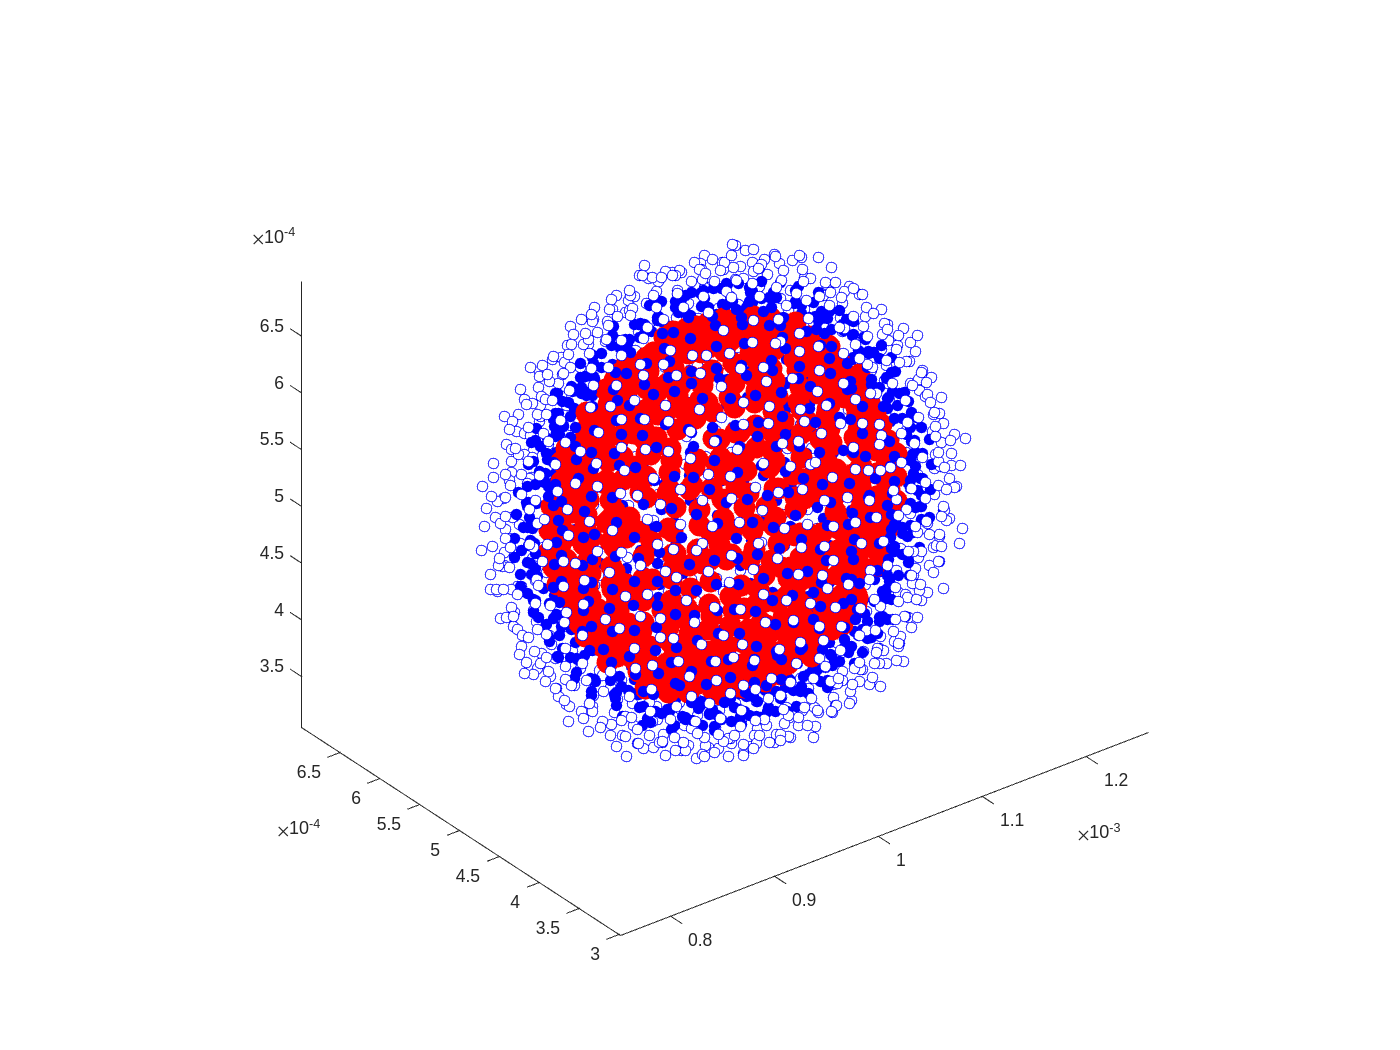

	number of fluid atoms in contact with solid 886


	number of solid atoms in contact with fluid 580 (neighbors 1035)


Calculate the 1921 x 1921 pair distances...
	 ... done in 0.00441 s
Find atoms within cuttoff...
	 ... done in 0.00554 s
Build the Verlet list...
	 ... done in 0.048 s [min=9, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.00506 s
buildVerletList: all done in 0.0733 s for 1921 atoms


Calculate Landshoff forces between [1921 x 3] atoms...
	 ... done in 0.0234 s


Landshoff:  2.5%>  5.486e+11 |  25.0%>  1.374e+12 |  50.0%>  1.945e+12 |  75.0%>  2.589e+12 |  97.5%>  4.079e+12 | 886 values | average = 2.0424e+12 <-- TIMESTEP: 912000


Calculate the 1 x 1466 pair distances...
	 ... done in 0.000755 s
Find atoms within cuttoff...
	 ... done in 0.000838 s
Build the Verlet list...
	 ... done in 0.00931 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.00266 s
buildVerletList: all done in 0.0154 s for 1466 atoms


Hertz:  2.5%>  1.667e-08 |  25.0%>  4.027e-08 |  50.0%>  6.772e-08 |  75.0%>  8.849e-08 |  97.5%>   1.05e-07 | 580 values | average = 6.378e-08 <-- TIMESTEP: 912000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.376e-05




%% Stress Analysis in Reference Frame (PART 2)
% -------------------------------------------------
% This part focuses on evaluating the mechanical interactions and stress in a particular 
% frame. Specifically, we employ a late-stage frame (closer to steady-state conditions) to 
% derive insights into the types of contacts between fluid and solid atoms.
% 
% * `timestepforstress`: Time step selected for stress analysis.
% * `Xstress`: Data structure containing all relevant atomic information at the chosen time step.
% * `verletListCross`: A specialized Verlet list that segregates contacts based on atom types.
% * `isincontact`, `isincontactwithsolid`, `isincontactwithfluid`: Boolean fields that signify 
% whether an atom is in contact, and with which type of atom.
%
% Here we rely heavily on a short-cut-off Verlet list for efficiency, separating cross-terms
% and characterizing specific types of atomic interactions.

% General container for storing data for different timesteps
postdata = repmat(struct('type','Landshoff|Hertz','timestep',NaN,'Xfluid',[],'Xsolid',[],'force',[]),0,0);


% Extract the Specific Frame for Stress Interpretation
% Selects a time step that is presumably closer to the steady-state to perform stress analysis.
list_timestepforstess = unique(timesteps(ceil((0.1:0.1:0.9)*ntimesteps)));
nlist_timestepforstess = length(list_timestepforstess);

% Loop on all selected time steps
altxt = {'no plot','plot'};
for i_timestepforstess = 1:nlist_timestepforstess


    % current frame
    timestepforstress = list_timestepforstess(i_timestepforstess);
    Xstress = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timestepforstress); % middle frame
    doplot = ismember(timestepforstress,list_timestepforstess([1 end]));
    dispf('\n%s-\n[%d/%d] TIMESTEP = %d (%s)',repmat('-*',1,40),i_timestepforstess,nlist_timestepforstess,timestepforstress,altxt{doplot+1})


    % Categorization of Atom Types
    % Identifies the most and least populous atom types to discern between fluid and solid types.
    T = Xstress.ATOMS.type;
    natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
    [~,fluidtype] = max(natomspertype);
    [~,solidtype] = min(natomspertype);
    walltypes = setdiff(atomtypes,[fluidtype,solidtype]);

    % Boolean Classification of Atom Types
    Xstress.ATOMS.isfluid = Xstress.ATOMS.type==fluidtype;
    Xstress.ATOMS.issolid = Xstress.ATOMS.type==solidtype;

    % Verlet List Construction with Short Cutoff
    % Builds a Verlet list with a short cutoff distance, designed to identify only the closest neighbors.
    [verletList,cutoff,dmin,config,dist] = buildVerletList(Xstress.ATOMS,3*rbead);

    % Partition Verlet List Based on Atom Types
    % This Verlet list is partitioned based on atom types, distinguishing between interactions
    % that are exclusively fluid-fluid, solid-fluid, or solid-solid.
    verletListCross = partitionVerletList(verletList,Xstress.ATOMS);

    % Identify Contacting Atoms
    % The atoms that are in contact with each other are identified.
    Xstress.ATOMS.isincontact = ~cellfun(@isempty,verletListCross);
    Xstress.ATOMS.contacttypes = cellfun(@(v) Xstress.ATOMS.type(v)',verletListCross,'UniformOutput',false);

    % Identify Atoms in Contact with Solids and Fluids
    % Further filters the atoms in contact to identify which are in contact with solids and which with fluids.
    Xstress.ATOMS.isincontactwithsolid = cellfun(@(c) ismember(solidtype,c), Xstress.ATOMS.contacttypes);
    Xstress.ATOMS.isincontactwithfluid = cellfun(@(c) ismember(fluidtype,c), Xstress.ATOMS.contacttypes);

    % Flag Fluid Atoms in Contact with Solid and Vice Versa
    % Identifies fluid atoms that are in contact with solid atoms and solid atoms in contact with fluid atoms.
    Xstress.ATOMS.fluidincontactwithsolid = Xstress.ATOMS.isfluid & Xstress.ATOMS.isincontactwithsolid;
    Xstress.ATOMS.solidincontactwithfluid = Xstress.ATOMS.issolid & Xstress.ATOMS.isincontactwithfluid;

    % Identify Indices for Analysis
    % Indices of fluid and solid atoms that are in contact with each other.
    ifluidcontact = find(Xstress.ATOMS.fluidincontactwithsolid);
    isolidcontact = find(Xstress.ATOMS.solidincontactwithfluid);

    % Extend Fluid Atoms Set with Neighbors (Not Directly in Contact)
    % Extends the set of fluid atoms under consideration to include their closest neighbors.
    ifluidcontact_withneighbors = unique(union(ifluidcontact,cat(2,verletList{ifluidcontact}))); % include neighbors
    ifluidcontact_withneighbors = ifluidcontact_withneighbors(T(ifluidcontact_withneighbors)==fluidtype); % filter, keep only fluids
    [~,~,ind_withoutneighbors] = intersect(ifluidcontact,ifluidcontact_withneighbors,'stable');
    notneighboringcontacts = setdiff(ifluidcontact_withneighbors,ifluidcontact_withneighbors(ind_withoutneighbors));

    % Visualization for some frames
    % filled red: solid "atoms" in contact with the fluid
    % filled blue: fluid "atoms" in contact with the solid (crown/shell)
    % empty blue: fluid "atoms" neighbor of previous ones but not contact
    % empty blue are used to calculate Landshoff forces at the position of filled ones
    if doplot
        figure, hold on
        plot3D(Xstress.ATOMS{ifluidcontact,{'x','y','z'}},'bo','markerfacecolor','b')
        plot3D(Xstress.ATOMS{notneighboringcontacts,{'x','y','z'}},'bo','markerfacecolor','w')
        plot3D(Xstress.ATOMS{isolidcontact,{'x','y','z'}},'ro','markersize',12,'markerfacecolor','r')
        axis equal, view(3), drawnow
        dispf('\tnumber of fluid atoms in contact with solid %d', length(ifluidcontact))
        dispf('\tnumber of solid atoms in contact with fluid %d (neighbors %d)', length(isolidcontact),length(notneighboringcontacts))
    end

    % Landshoff forces in the fluid
    %
    % This section is dedicated to the calculation of Landshoff forces in the fluid medium.
    % The computation is confined to a shell or "crown" around the solid particles.
    % Here, we build a new Verlet list specific to the fluid particles around solid structures.
    %
    % * `Xfluidcontact_withneighbors`: Atomic information specifically for the fluid atoms in the vicinity of the solid.
    % * `Vfluidcontact_withneighbors`: Verlet list constructed for these neighboring fluid atoms.
    % * `Flandshoff`: Landshoff forces calculated based on the new Verlet list.
    % * `f`: Magnitude of the Landshoff forces.
    %
    % Finally, visualization aids are employed to graphically represent these forces and their directions.


    % Extract Information for Fluid Atoms in Contact with Neighbors
    % Obtains the atomic information for fluid atoms in the vicinity of solid atoms, as identified earlier.
    Xfluidcontact_withneighbors = Xstress.ATOMS(ifluidcontact_withneighbors,:);

    % Verlet List Construction for Fluid Atoms
    % Constructs a Verlet list for these neighboring fluid atoms with a larger cutoff (4*rbead).
    Vfluidcontact_withneighbors = buildVerletList(Xfluidcontact_withneighbors,4*rbead);

    %%% Compute Landshoff Forces
    % Computes Landshoff forces based on the new Verlet list.
    % The config structure (configLandshoff) should match the input values of the simulation or equivalent
    hLandshoff = 5*rbead; %1.25e-5; % m
    configLandshoff = struct( ...
        'gradkernel', kernelSPH(hLandshoff,'lucyder',3),...kernel gradient
        'h', hLandshoff,...smoothing length (m)
        'c0',0.32,...speed of the sound (m/s)
        'q1',30,... viscosity coefficient (-)
        'rho', 1000 ...density
        );
    Flandshoff = forceLandshoff(Xfluidcontact_withneighbors,[],Vfluidcontact_withneighbors,configLandshoff);

    % Restrict to the Crown/Shell Around the Solid
    % Filters out the Landshoff forces, focusing only on the "crown" or shell around the solid atoms.
    Flandshoff = double(Flandshoff(ind_withoutneighbors,:)); % we restrict only to the crown/shell
    flandshoff = sqrt(sum(Flandshoff.^2,2));
    statvec(flandshoff,'Landshoff',sprintf('<-- TIMESTEP: %d',timestepforstress))

    %%% Store the current result
    postdata(end+1).type = 'Landshoff'; % end+1 triggers a new object
    postdata(end).timestep = timestepforstress; % we fill it with end
    postdata(end).Xfluid = Xstress.ATOMS(ifluidcontact,:);
    postdata(end).Xsolid = Xstress.ATOMS(isolidcontact,:);
    postdata(end).force = Flandshoff;

    %%% Compute Hertz contacts
    % Extract Information for Fluid Atoms in Contact
    Xcontactregion = Xstress.ATOMS(union(ifluidcontact,isolidcontact),:);
    % Verlet List Construction for Solid Atoms (only) and considering only Fluid Atoms as neighbors
    [Vcontactregion,~,dmincontact] = buildVerletList(Xcontactregion,3*rbead,[],[],[],Xcontactregion.isfluid,Xcontactregion.issolid);
    % Compute Hertz Forces
    Rfluid = 1.04e-5; % m
    Rsolid = 1.56e-5; % m
    Rfluid = Rsolid;
    configHertz = struct('R',{Rsolid Rfluid},'E',2000);
    FHertz = forceHertz(Xcontactregion,Vcontactregion,configHertz);
    fhertz = sqrt(sum(FHertz.^2,2));
    fhertzcontacts = fhertz(fhertz>0);
    statvec(fhertzcontacts,'Hertz',sprintf('<-- TIMESTEP: %d\n\tsubjected to Rsolid=[%0.4g %0.4g] dmin/2=%0.4g',timestepforstress,configHertz(1).R,configHertz(2).R,dmincontact/2))

    %%% Store current results
    % Store the current result
    postdata(end+1).type = 'Hertz'; % end+1 triggers a new object
    postdata(end).timestep = timestepforstress; % we fill it with end
    postdata(end).Xfluid = [];
    postdata(end).Xsolid = Xcontactregion(fhertz>0,:);
    postdata(end).force = FHertz(fhertz>0);

end % next i_timestepforstess

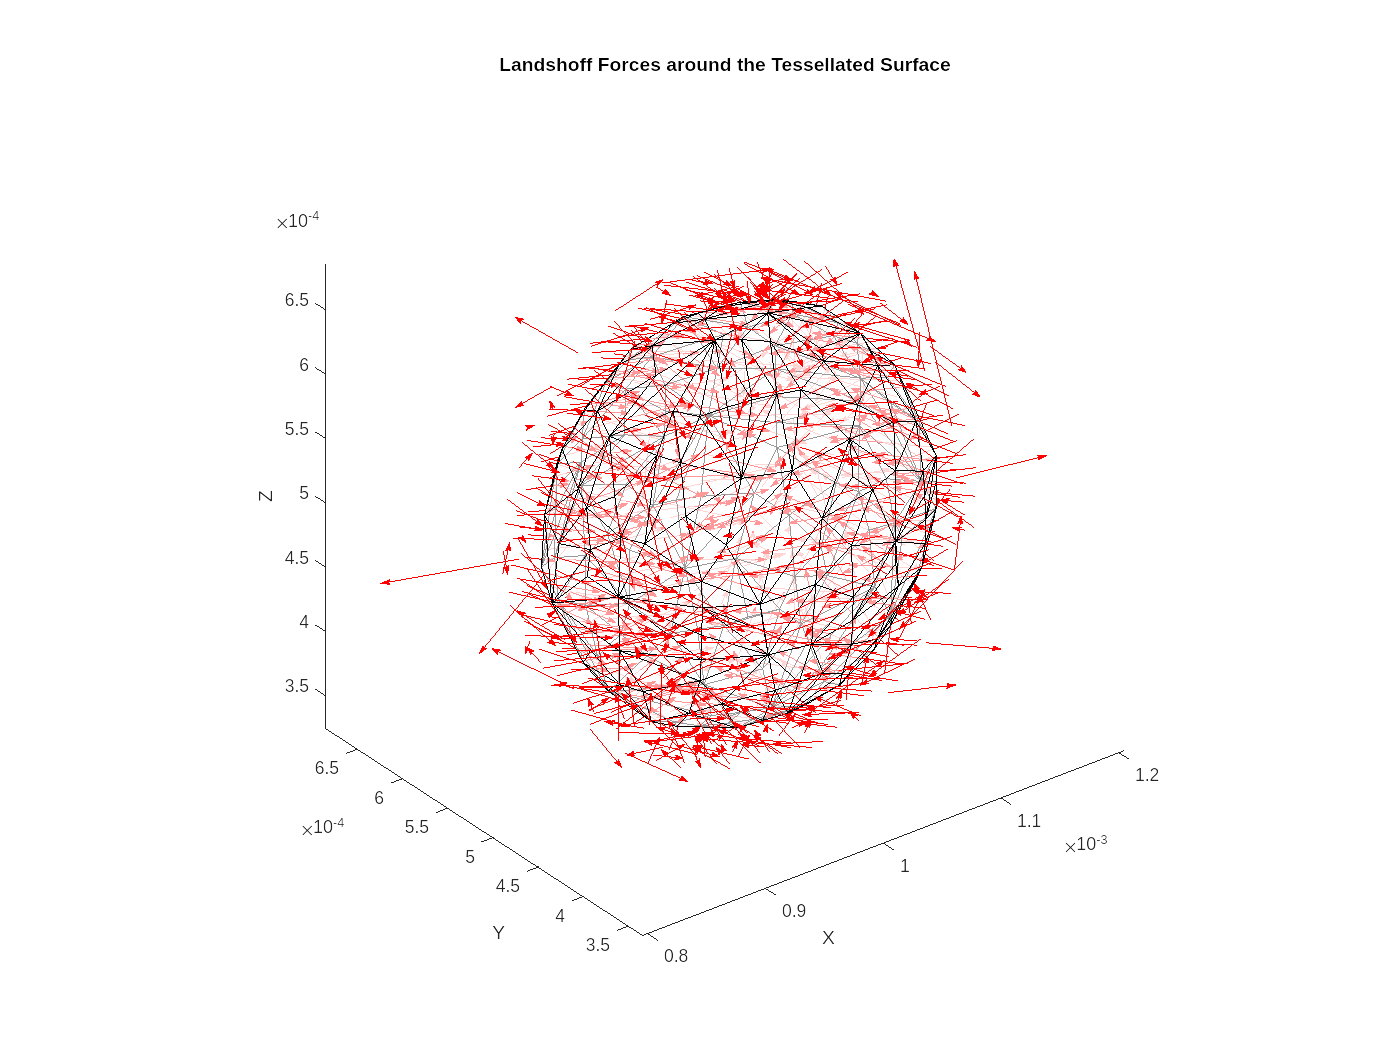


%% Visualization (bead-based) of Landshoff forces
% Creates a 3D visualization featuring both the solid structure and the fluid atoms under consideration.
% The Landshoff forces are represented as arrows originating from the fluid atoms.

% Tesselated Solid Visualization
% Utilizes Delaunay triangulation to represent the solid structure.
DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact,{'x','y','z'}}));
K = convexHull(DT);
figure, hold on
trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), 'FaceColor', 'w','Edgecolor','k','FaceAlpha',0.6);
axis equal; view(3)

% Visualization of Fluid Atoms and Landshoff Forces
% Landshoff forces are scaled and then visualized as arrows.
% fluid around
% scatter3D(Xfluidcontact_withneighbors{ind_withoutneighbors,{'x','y','z'}},f);
fmedian = median(flandshoff);
fmin = fmedian/50;
fscale = 4*rbead/fmedian;
start = Xfluidcontact_withneighbors{ind_withoutneighbors,{'x','y','z'}};
stop = start + Flandshoff * fscale;
start(flandshoff<fmin,:) = []; % non-significant forces are removed
stop(flandshoff<fmin,:) = [];
ha = arrow(start,stop,'length',4,'BaseAngle',60,'color','r');
axis equal, view(3)
title('Landshoff Forces around the Tessellated Surface');
xlabel('X'); ylabel('Y'); zlabel('Z')

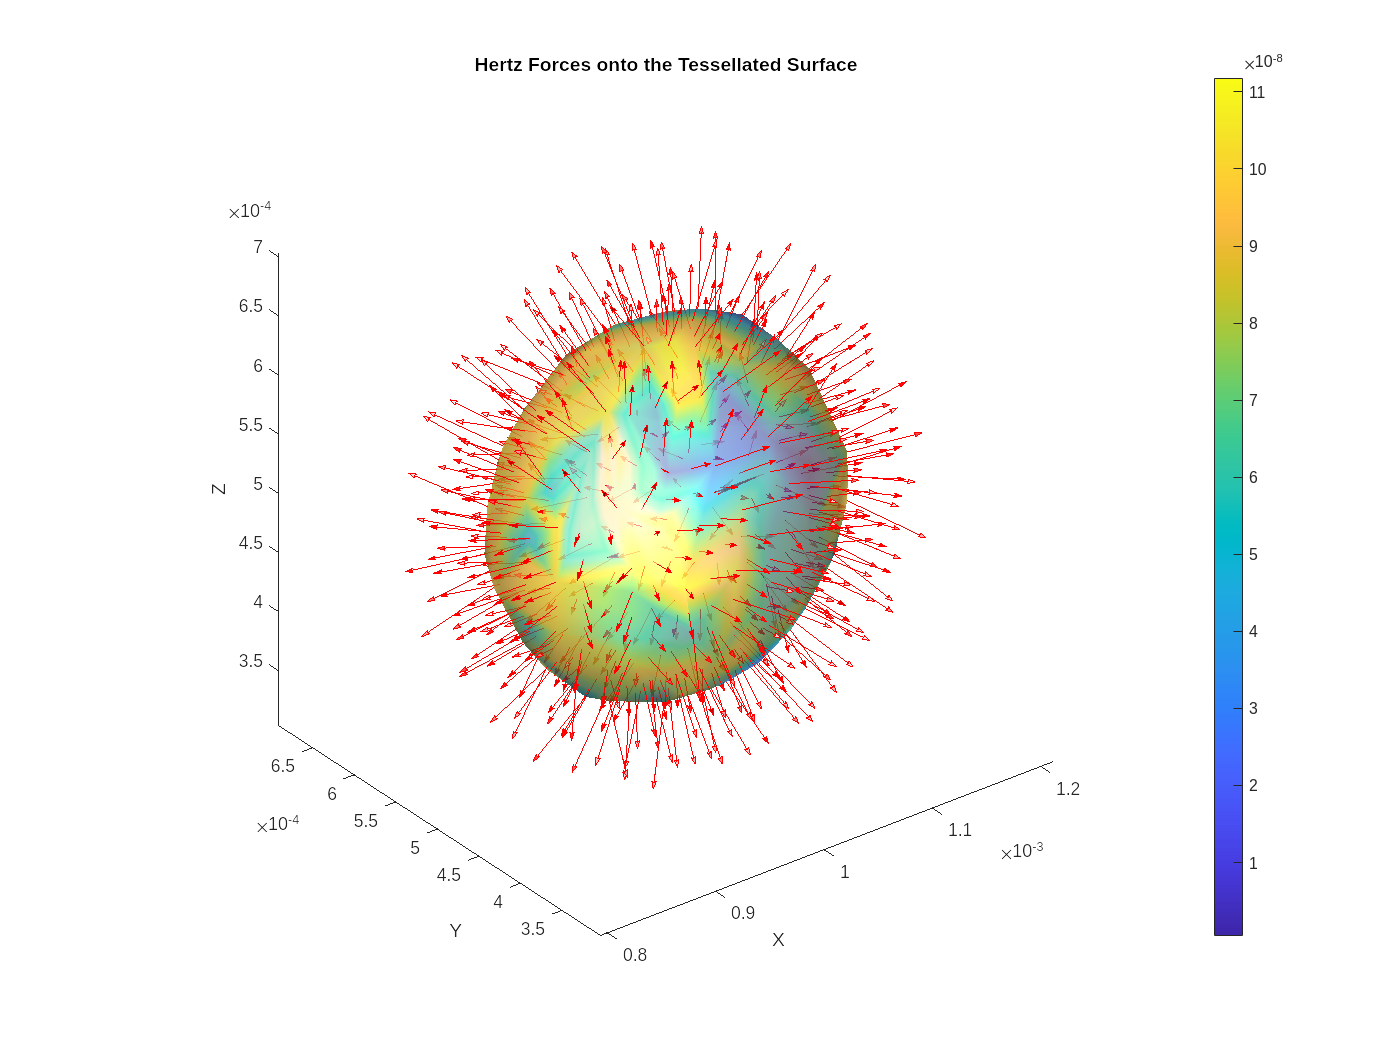


% Similar Visualization for Hertz Contacts
warning off
figure, hold on
fmedian = median(fhertzcontacts);
fmin = fmedian/50;
fscale = 4*rbead/fmedian;
start = Xcontactregion{fhertz>0,{'x','y','z'}};
stop = start - FHertz(fhertz>0,:) * fscale; % outwards forces (preferred)
start(fhertzcontacts<fmin,:) = []; % non-significant forces are removed
stop(fhertzcontacts<fmin,:) = [];
D = pdist2(DT.Points, start); % Compute pairwise distance
[~, idx] = min(D, [], 2); % Find closest particles on the mesh
trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), fhertzcontacts(idx),'Edgecolor','k','FaceAlpha',0.6);
axis equal; view(3), camlight('headlight'); camlight('left'); lighting phong; colorbar;
shading interp
ha = arrow(start,stop,'length',4,'BaseAngle',60,'color','r');
axis equal, view(3)
title('Hertz Forces onto the Tessellated Surface');
xlabel('X'); ylabel('Y'); zlabel('Z')

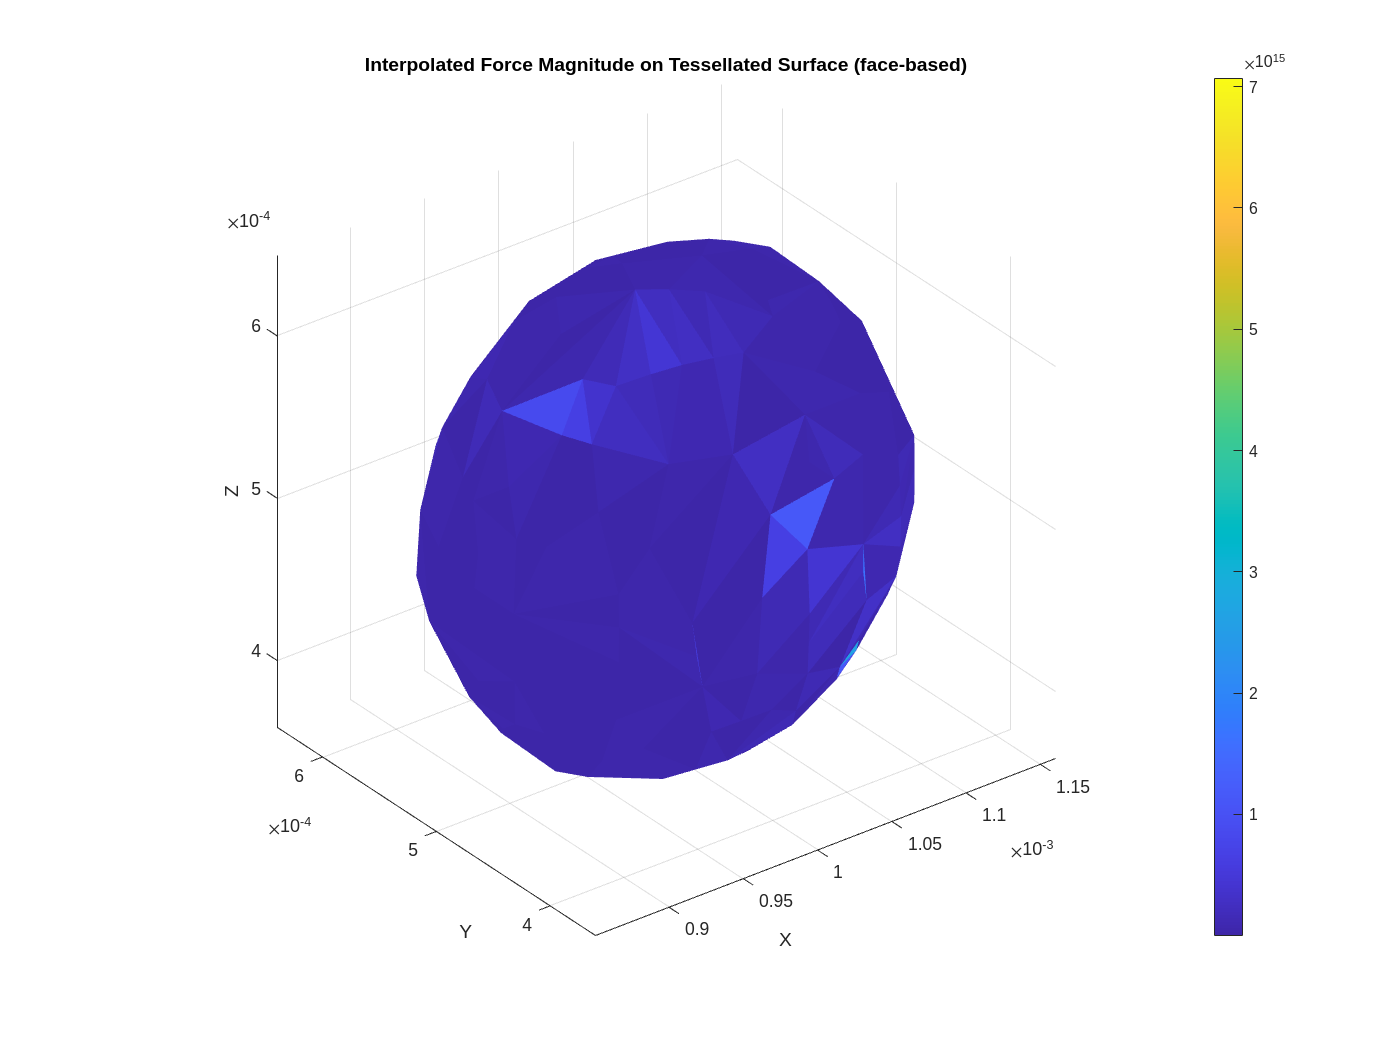


%% Project Landshoff Forces onto the Tessellated Surface
% Allocate space for the projected forces.
FprojectedN = zeros(size(Flandshoff));
FprojectedT = zeros(size(Flandshoff));
% Extract vertex coordinates from Delaunay Triangulation object.
vertices = DT.Points;
% Loop through all fluid atoms in contact with the solid.
for i = 1:length(ind_withoutneighbors)
    % Get the position of the current fluid atom.
    fluidPos = Xfluidcontact_withneighbors{ind_withoutneighbors(i),{'x','y','z'}};
    % Find the closest vertex on the tessellated surface.
    dists = sum((vertices - fluidPos).^2, 2);
    [~, closestVertexIdx] = min(dists);
    closestVertex = vertices(closestVertexIdx, :);
    % Calculate the vector from the fluid atom to the closest surface vertex.
    surfaceToFluidVec = fluidPos - closestVertex;
    % Normalize the vector.
    surfaceToFluidVec = surfaceToFluidVec / norm(surfaceToFluidVec);
    % Get the Landshoff force acting on the fluid atom.
    landshoffForce = Flandshoff(i, :);
    % Project the Landshoff force onto the normal.
    % Here, surfaceToFluidVec serves as the approximation of the outward normal at the closest vertex.
    projectedForceN = dot(landshoffForce, surfaceToFluidVec) * surfaceToFluidVec;
    % Store the projected force.
    FprojectedN(i, :) = projectedForceN;
    FprojectedT(i, :) = landshoffForce-projectedForceN;
end

% At this point, Fprojected contains the Landshoff forces projected onto the surface normal.
% Interpolation and Stress Magnitude Visualization
% Get faces and vertices from the tessellation.
faces = K; % Faces are given by the convex hull indices
vertices = DT.Points; % Vertex coordinates

% Loop over all faces to interpolate force and stress.
% Compute Barycentric Interpolation of Forces
% Initialize an array to store the interpolated forces and stresses
FNinterp_face = zeros(size(faces, 1), 3);
FTinterp_face = zeros(size(faces, 1), 3);
SNinterp_face = zeros(size(faces, 1), 3); % Normal stress per unit area
STinterp_face = zeros(size(faces, 1), 3); % Tangential stress per unit area

% Loop over all faces.
for i = 1:size(faces, 1)
    % Vertices of the triangle.
    vertex_indices = faces(i, :);
    A = vertices(vertex_indices(1), :);
    B = vertices(vertex_indices(2), :);
    C = vertices(vertex_indices(3), :);
    % Surface area of the triangle using Heron's formula.
    AB = norm(A - B);
    AC = norm(A - C);
    BC = norm(B - C);
    s = (AB + AC + BC) / 2;
    area_triangle = sqrt(s * (s - AB) * (s - AC) * (s - BC));
    % Normal to faces
    N = cross(B - A, C - A);
    N = N / norm(N); % Normalizing the normal vector
    % Forces at the vertices.
    F_A = FprojectedN(vertex_indices(1), :) + FprojectedT(vertex_indices(1), :);
    F_B = FprojectedN(vertex_indices(2), :) + FprojectedT(vertex_indices(2), :);
    F_C = FprojectedN(vertex_indices(3), :) + FprojectedT(vertex_indices(3), :);
    % The centroid (P) of the triangle for interpolation.
    P = (A + B + C) / 3;
    % Barycentric weights.
    ABC_inv = inv([A; B; C]);
    w = ABC_inv * P';
    % Interpolate the force at the centroid.
    Finterp = w(1) * F_A + w(2) * F_B + w(3) * F_C; 
    % Decompose the force into normal and tangential components
    F_N = dot(Finterp, N) * N; % only the normal force is trivial to compute
    F_T = Finterp - F_N; % by subtraction we get the tangential
    % Store interpolated force.
    Finterp_face(i, :) = Finterp;
    % Compute normal and tangential stress per unit area (Force/Area)
    SNinterp_face(i, :) = F_N / area_triangle;
    STinterp_face(i, :) = F_T / area_triangle;
end
% Compute the magnitude of interpolated stress.
face_force_magnitude = sqrt(sum(Finterp_face.^2, 2));
face_stressN_magnitude = sqrt(sum(SNinterp_face.^2, 2));
face_stressT_magnitude = sqrt(sum(STinterp_face.^2, 2));


% Add the smoothed force at vertices
% In computational geometry, the "valence" of a vertex refers to the number of edges
% (or equivalently, faces for a triangular mesh) incident to it. Valence can serve as
% an important metric in mesh quality and adaptivity considerations. 
% In our case, the valence is expected high (up to 11,12 faces per vertex), then poor mesh
uniq_vertex_indices = unique(faces(:)); % Find unique vertices used in faces
uniq_vertices = vertices(uniq_vertex_indices, :); % Create a new vertices array based on these unique indices
mapping = NaN(size(vertices, 1), 1); % Create a mapping from old vertex indices to new ones
mapping(uniq_vertex_indices) = 1:length(uniq_vertex_indices);
uniq_faces = mapping(faces); % Update the faces array to reflect new vertex indices
% Initialize interpolated forces at vertices
Finterp_vertex = zeros(size(uniq_vertices, 1), 3);
SNinterp_vertex = zeros(size(uniq_vertices, 1), 3);
STinterp_vertex = zeros(size(uniq_vertices, 1), 3);
% Create a mapping from vertices to faces
vertex_to_faces = cell(size(uniq_vertices, 1), 1);
for i = 1:size(uniq_faces, 1)
    for j = 1:3 % for each Vertex
        vertex_to_faces{uniq_faces(i, j)} = [vertex_to_faces{uniq_faces(i, j)}; i]; % we add the ith face
    end
end
% Interpolate forces at each vertex
for i = 1:size(uniq_vertices, 1)
    adjacent_faces = vertex_to_faces{i};
    if ~isempty(adjacent_faces)
        Finterp_vertex(i, :) = mean(Finterp_face(adjacent_faces, :), 1);
        SNinterp_vertex(i, :) = mean(SNinterp_face(adjacent_faces, :), 1);
        STinterp_vertex(i, :) = mean(STinterp_face(adjacent_faces, :), 1);
    end
end
vertex_force_magnitude = sqrt(sum(Finterp_vertex.^2, 2));
vertex_stressN_magnitude = sqrt(sum(SNinterp_vertex.^2, 2));
vertex_stressT_magnitude = sqrt(sum(STinterp_vertex.^2, 2));

% Visualization (face-based, less smooth)
figure;
trisurf(faces, vertices(:, 1), vertices(:, 2), vertices(:, 3), face_force_magnitude, 'EdgeColor', 'none');
axis equal; view(3);
colorbar;
title('Interpolated Force Magnitude on Tessellated Surface (face-based)');
xlabel('X'); ylabel('Y'); zlabel('Z')

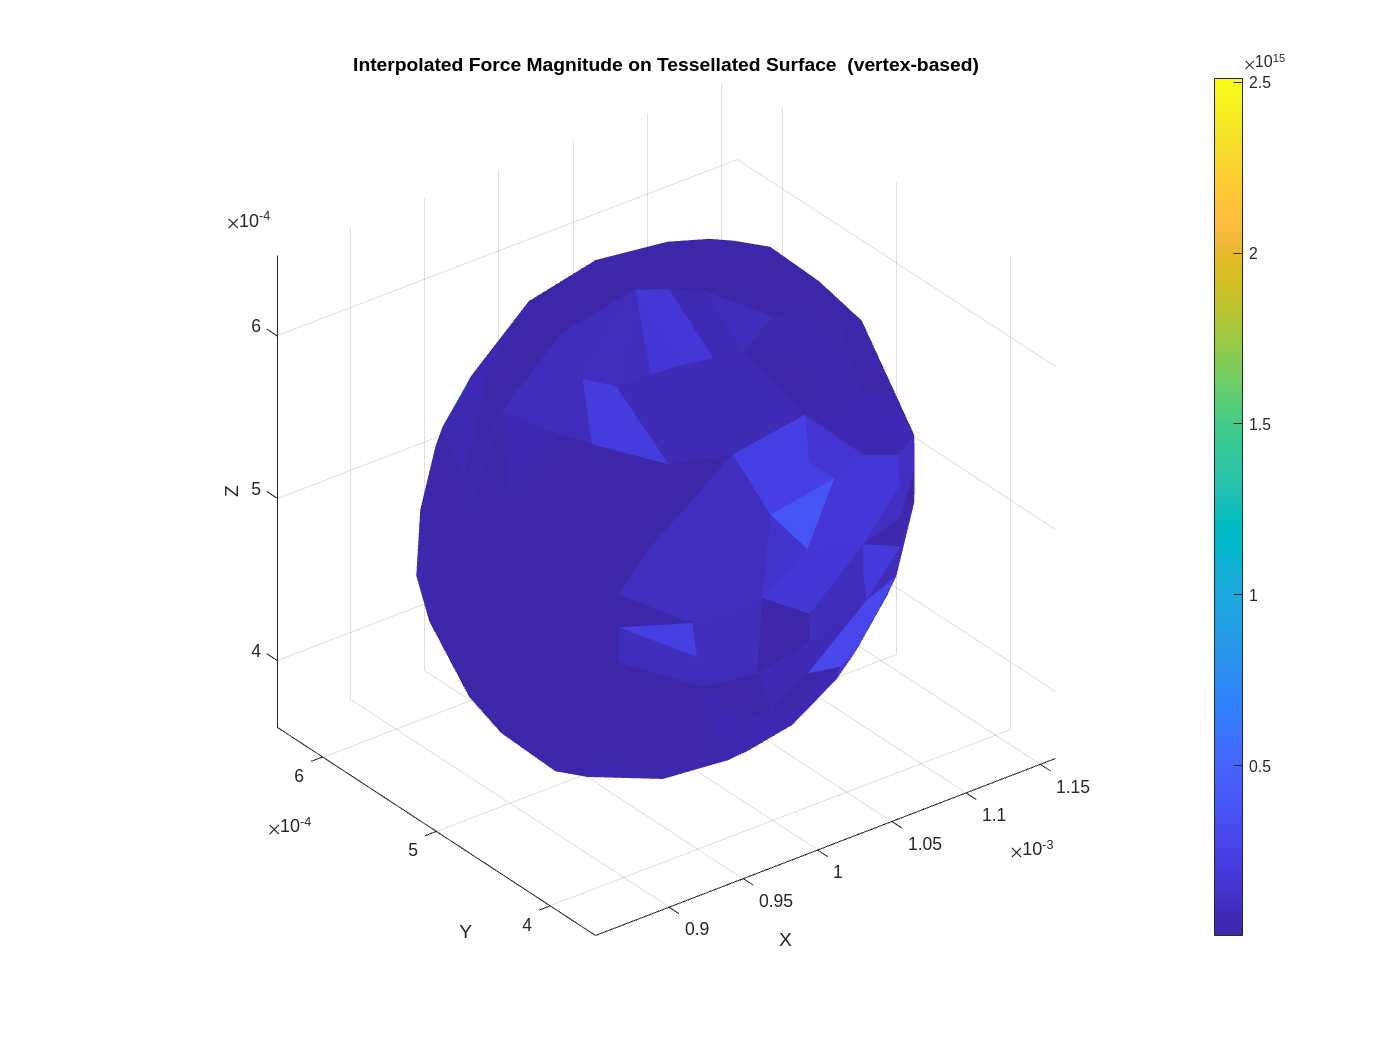


% Visualization (vertex-based, more smooth)
figure;
trisurf(uniq_faces, uniq_vertices(:, 1), uniq_vertices(:, 2), uniq_vertices(:, 3), vertex_force_magnitude, 'EdgeColor', 'none');
axis equal; view(3);
colorbar;
title('Interpolated Force Magnitude on Tessellated Surface  (vertex-based)');
xlabel('X'); ylabel('Y'); zlabel('Z')

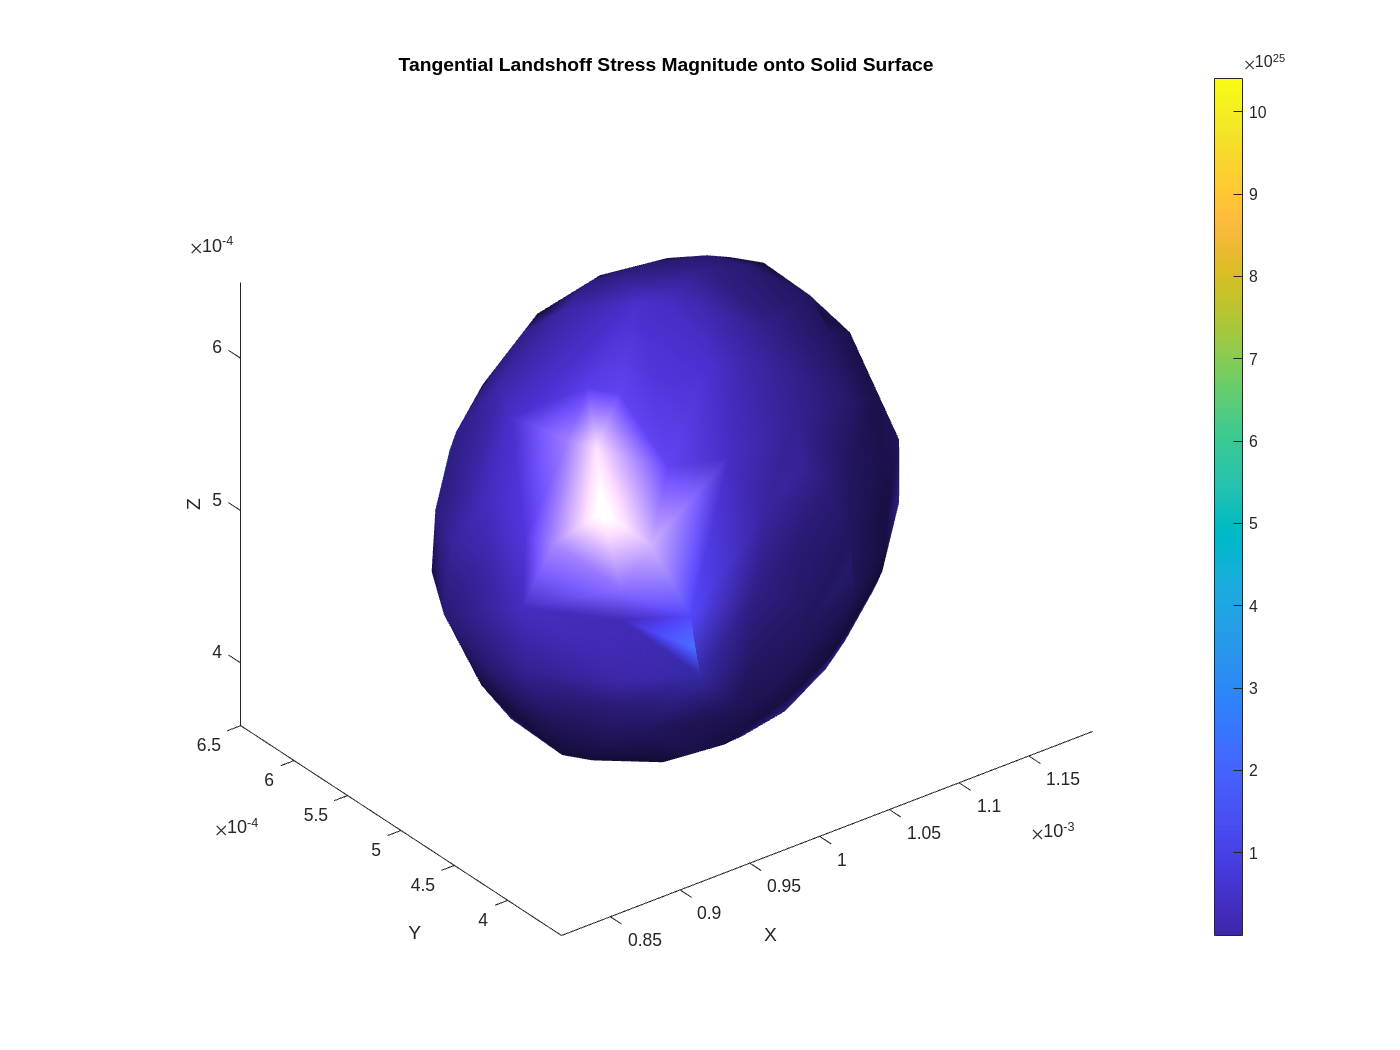


% Optimized visualization using 'patch' for stresses
% only vertex_stressT_magnitude is meaningful
figure;
patch_data.Vertices = uniq_vertices; % Prepare data for 'patch' function
patch_data.Faces = uniq_faces;
patch_data.FaceVertexCData = vertex_stressT_magnitude;
patch_data.FaceColor = 'interp';
patch_data.EdgeColor = 'none';
% Calculate vertex normals for smooth shading
patch_data.VertexNormals = -vertexNormal(triangulation(uniq_faces, uniq_vertices));
% Create the surface plot
p = patch(patch_data);
% Set view and lighting
axis equal;
view(3); camlight('headlight'); camlight('left'); lighting phong; colorbar;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Tangential Landshoff Stress Magnitude onto Solid Surface');

% Option to remove grid for a cleaner look
% grid off;
